# Rectangle Detection in Image (Notebook Style)

This script allows interactive visualization of rectangle detection steps

## Load Image


img = meanFrameCroppedHoriz;

## Convert to Grayscale (if needed)

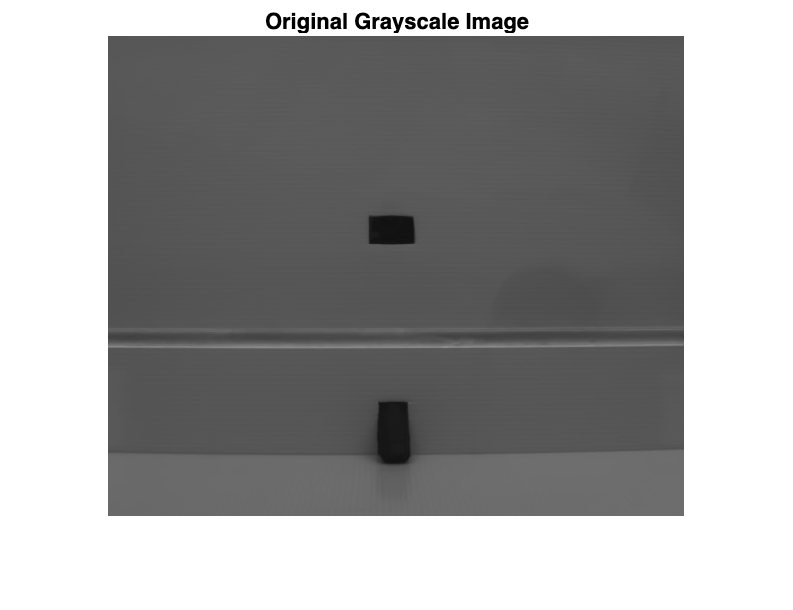

if size(img, 3) == 3
    grayImg = rgb2gray(img);
else
    grayImg = img;
end

figure; imshow(grayImg); title('Original Grayscale Image');

## Contrast Enhancement (Optional, if contrast is low)

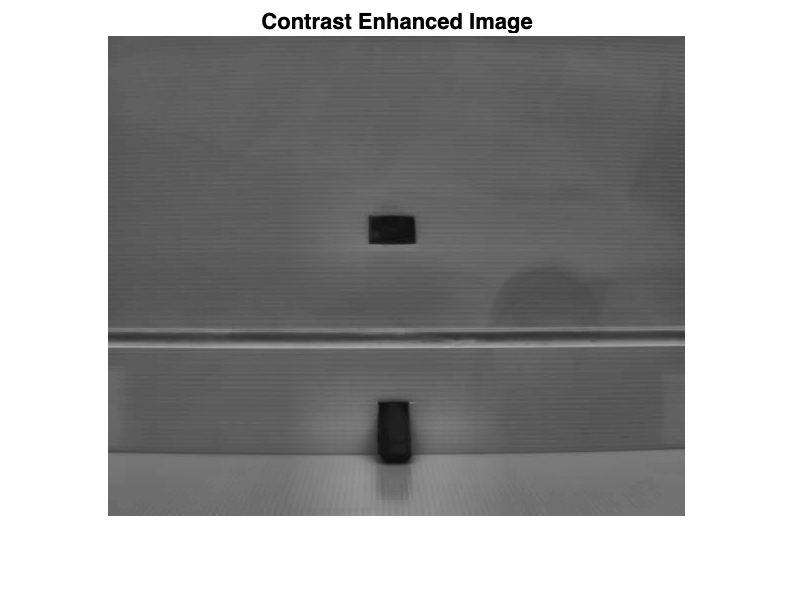

enhancedImg = adapthisteq(grayImg);
figure; imshow(enhancedImg); title('Contrast Enhanced Image');

## Thresholding

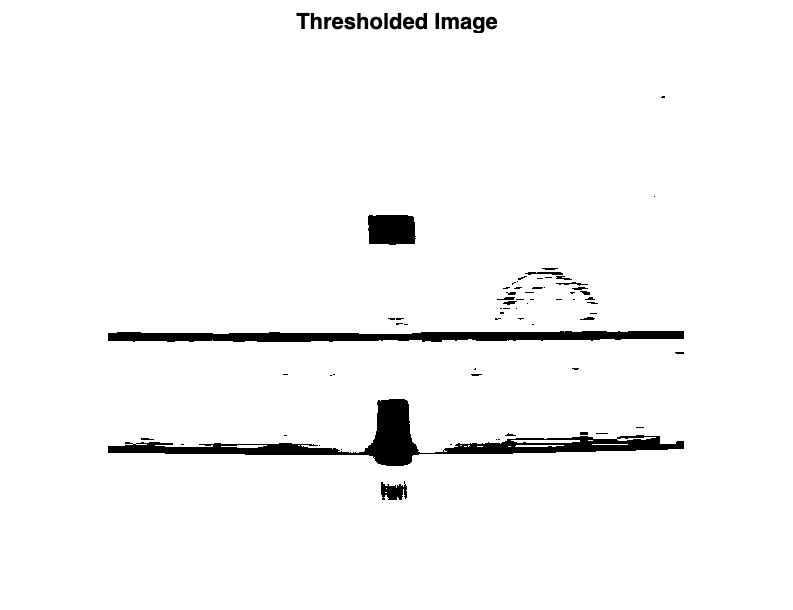

bw = imbinarize(enhancedImg, 'adaptive', 'ForegroundPolarity', 'dark');
figure; imshow(bw); title('Thresholded Image');

## Morphological Processing (Noise Removal)

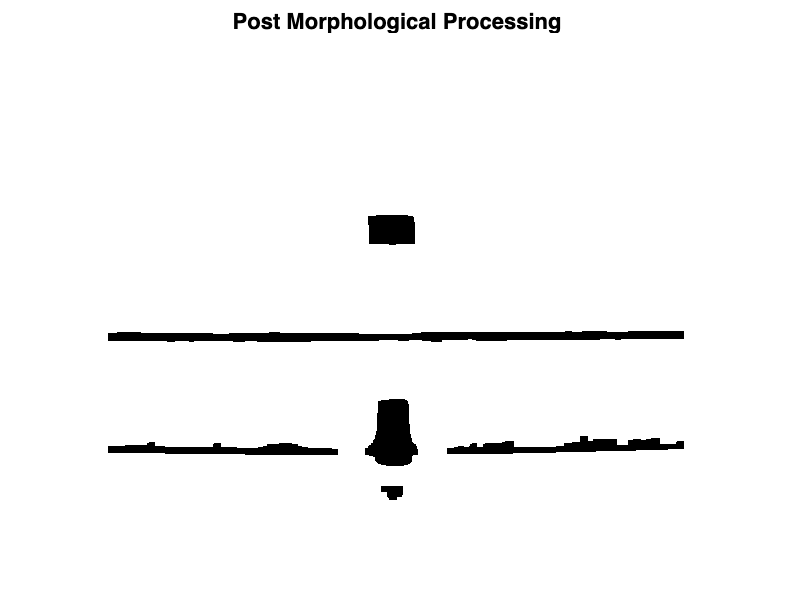

bw = imclose(bw, strel('rectangle', [5,5])); % Fill small gaps
bw = imopen(bw, strel('rectangle', [3,3]));  % Remove small noise
figure; imshow(bw); title('Post Morphological Processing');

## Detect Regions with Bounding Boxes

stats = regionprops(bw, 'BoundingBox', 'Area', 'Extent');

## Filter Based on Rectangle Properties

minArea = 1000; % Adjust if needed
validRects = [];
for k = 1:length(stats)
    bb = stats(k).BoundingBox;
    aspectRatio = bb(3) / bb(4);
    extent = stats(k).Area / (bb(3) * bb(4));
    
    if stats(k).Area > minArea && extent > 0.8
        validRects = [validRects; bb];  % Store detected rectangles
    end
end

## Display Detected Rectangles

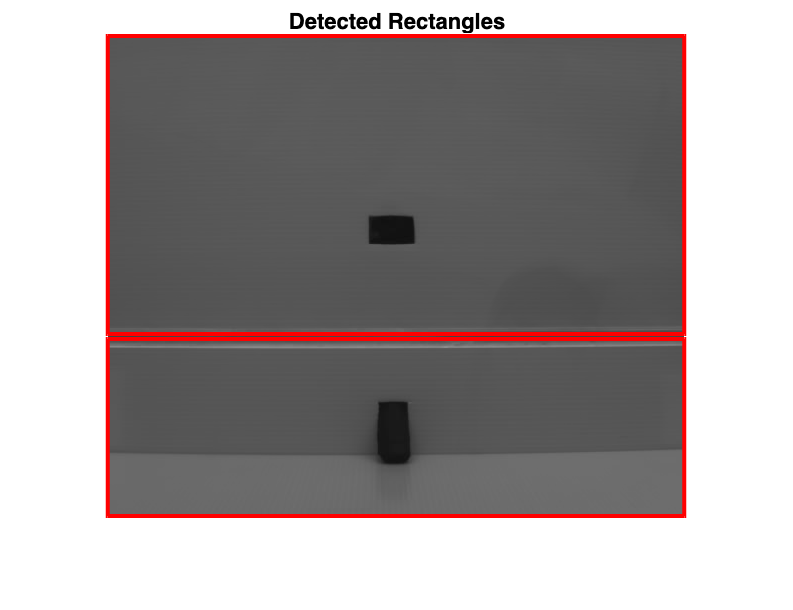

figure; imshow(meanImage); hold on;
for i = 1:size(validRects, 1)
    rectangle('Position', validRects(i,:), 'EdgeColor', 'r', 'LineWidth', 2);
end
hold off;
title('Detected Rectangles');